# Matrix Computations

# CPSC 5006-EL

## Assignment2

### **Haoliang Sheng 0441916**

### **Q1**

A = [36 30 24;30 34 26;24 26 21];
B = [1 -1 1 -1 1;-1 2 -2 2 -2;1 -2 3 -3 3;-1 2 -3 4 -4;1 -2 3 -4 5];
C = [1 2 3;2 5 10;3 10 16];

#### **1)**

Please refer to cholesky_innerproduct.m

cholesky_innerproduct(A)

ans =      6     5     4
     0     3     2
     0     0     1


cholesky_innerproduct(B)

ans =      1    -1     1    -1     1
     0     1    -1     1    -1
     0     0     1    -1     1
     0     0     0     1    -1
     0     0     0     0     1


cholesky_innerproduct(C)


ans =

     []



#### 2)

Please refer to cholesky_outerproduct.m

cholesky_outerproduct(A)

ans =      6     5     4
     0     3     2
     0     0     1


cholesky_outerproduct(B)

ans =      1    -1     1    -1     1
     0     1    -1     1    -1
     0     0     1    -1     1
     0     0     0     1    -1
     0     0     0     0     1


cholesky_outerproduct(C)


ans =

     []



### Q2

#### 1)

Please refer to forward.m and backward.m

A = [36 -30 24;-30 34 -26;24 -26 21];
b = [0;12;-7];
R = cholesky_innerproduct(A)

R =      6    -5     4
     0     3    -2
     0     0     1


y = forward(R', b)

y =      0
     4
     1


x = backward(R, y)

x =      1
     2
     1


#### 2)

A = [1 1 1 1 1;1 2 2 2 2;1 2 3 3 3;1 2 3 4 4;1 2 3 4 5];
b = [5;9;12;14;15];
R = cholesky_innerproduct(A)

R =      1     1     1     1     1
     0     1     1     1     1
     0     0     1     1     1
     0     0     0     1     1
     0     0     0     0     1


y = forward(R', b)

y =      5
     4
     3
     2
     1


x = backward(R, y)

x =      1
     1
     1
     1
     1


### Q3


$$\textrm{number}\;\textrm{of}\;\textrm{upper}\;\textrm{triangle}\;\textrm{members}=1+2+\cdots +n=\frac{n\left(n+1\right)}{2}$$



$$\textrm{number}\;\textrm{of}\;\textrm{envelope}\;\textrm{members}=n-2+n-1=2n-3$$



$$\textrm{fraction}=\frac{2*\left(2n-3\right)}{n\left(n+1\right)}=\frac{4n-6}{n^2 +n}$$


### Q4

backward

for each n rows

    b(i) = b(i) - a(i,j)*b(j);

    There are at most s multiplication and minus operations, other a(i, j>i+s)=0

    So, there are at most 2s flops

end

Therefore, there are at most 2ns flops

### Q5

m = 20;
r = zeros(1,m); r(1)=2; r(2)=-1;
B = sparse(toeplitz(r));
C = speye(m);
A = kron(kron(B,C),C) + ...
    kron(kron(C,B),C) + ...
    kron(kron(C,C),B);

size(A)

ans =         8000        8000


issparse(A)

ans = logical
   1


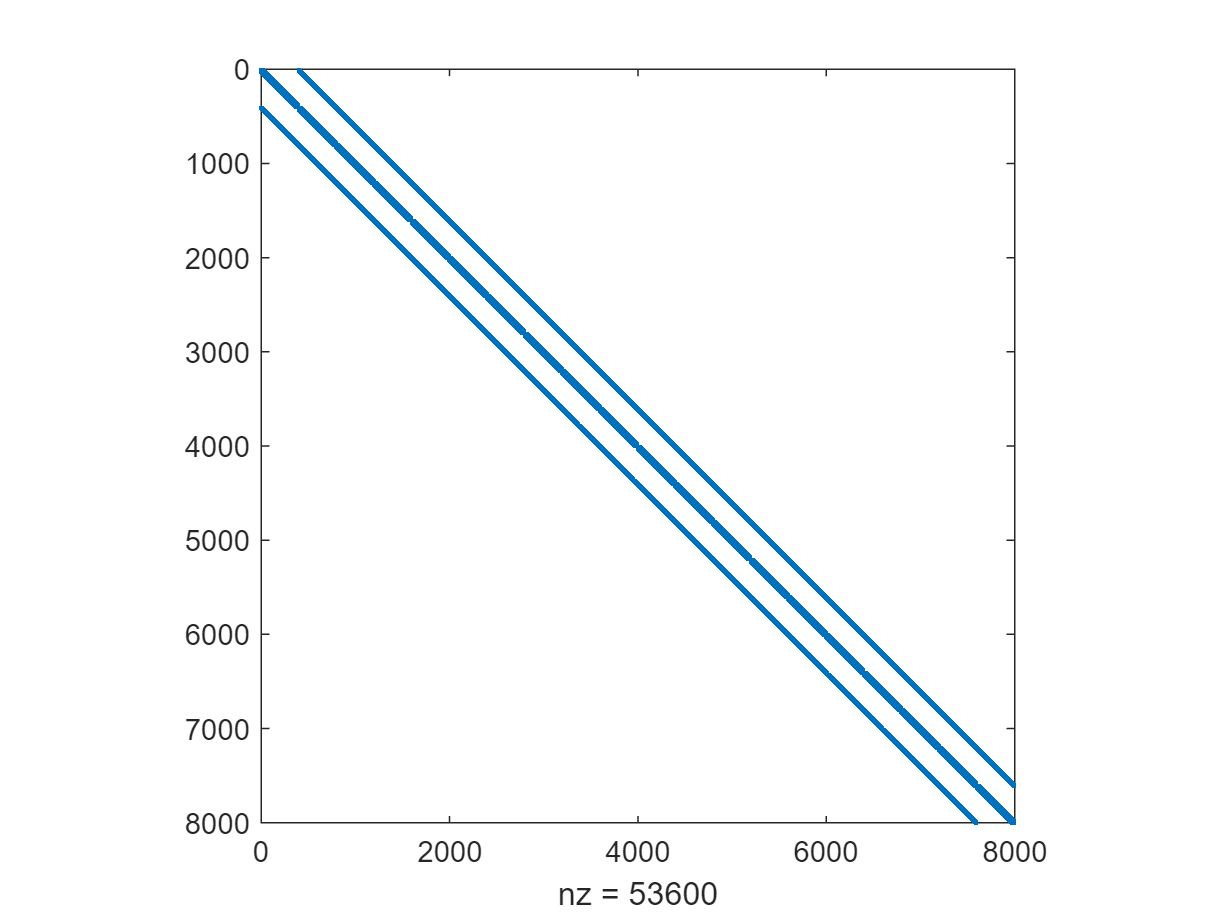

spy(A)

nnz(A)

ans = 53600

#### a)

tic, R = chol(A); toc

历时 0.133699 秒。


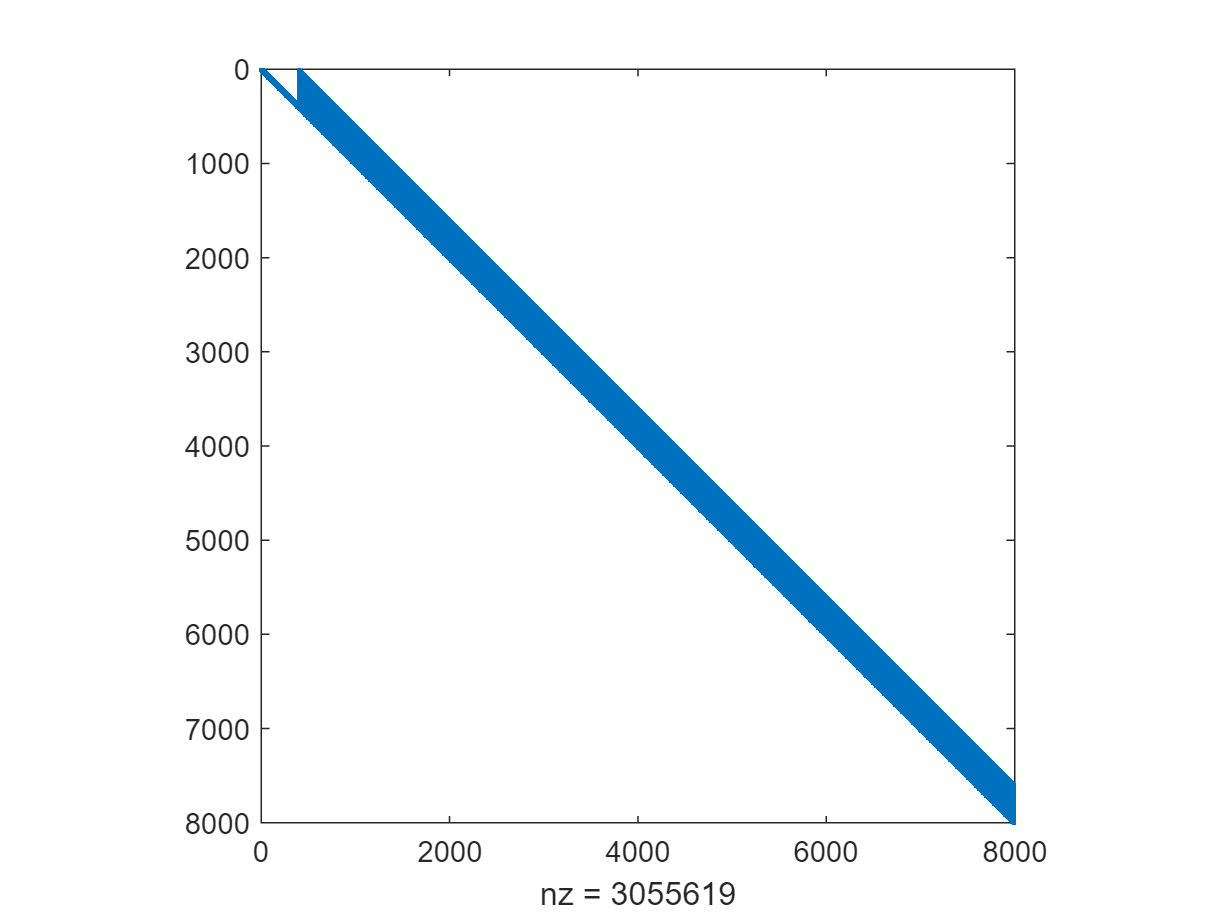

spy(R)

#### b)

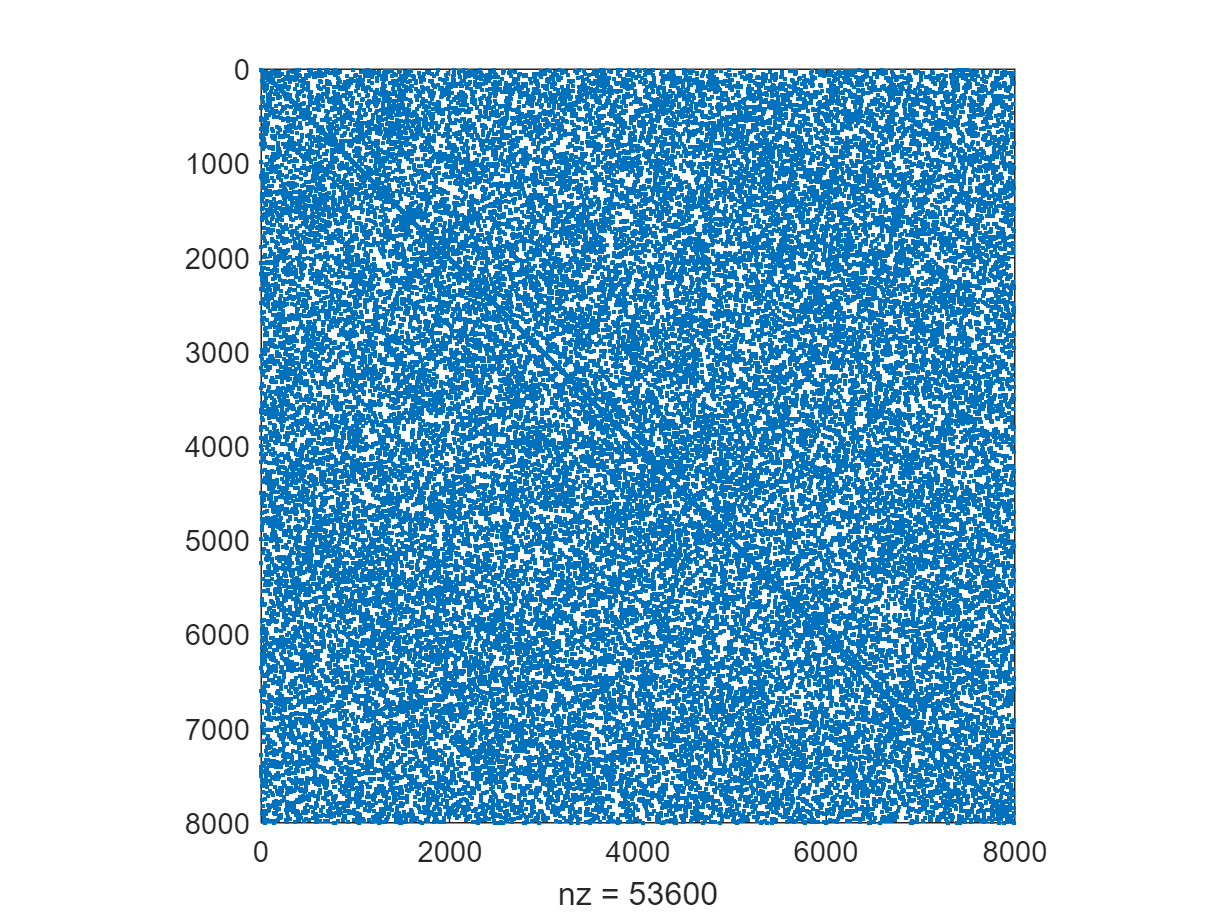

p = randperm(size(A,1));
arnd = A(p,p);
spy(arnd)

tic, rrnd = chol(arnd); toc

历时 3.704967 秒。


nz = nnz(rrnd)

nz = 12056848

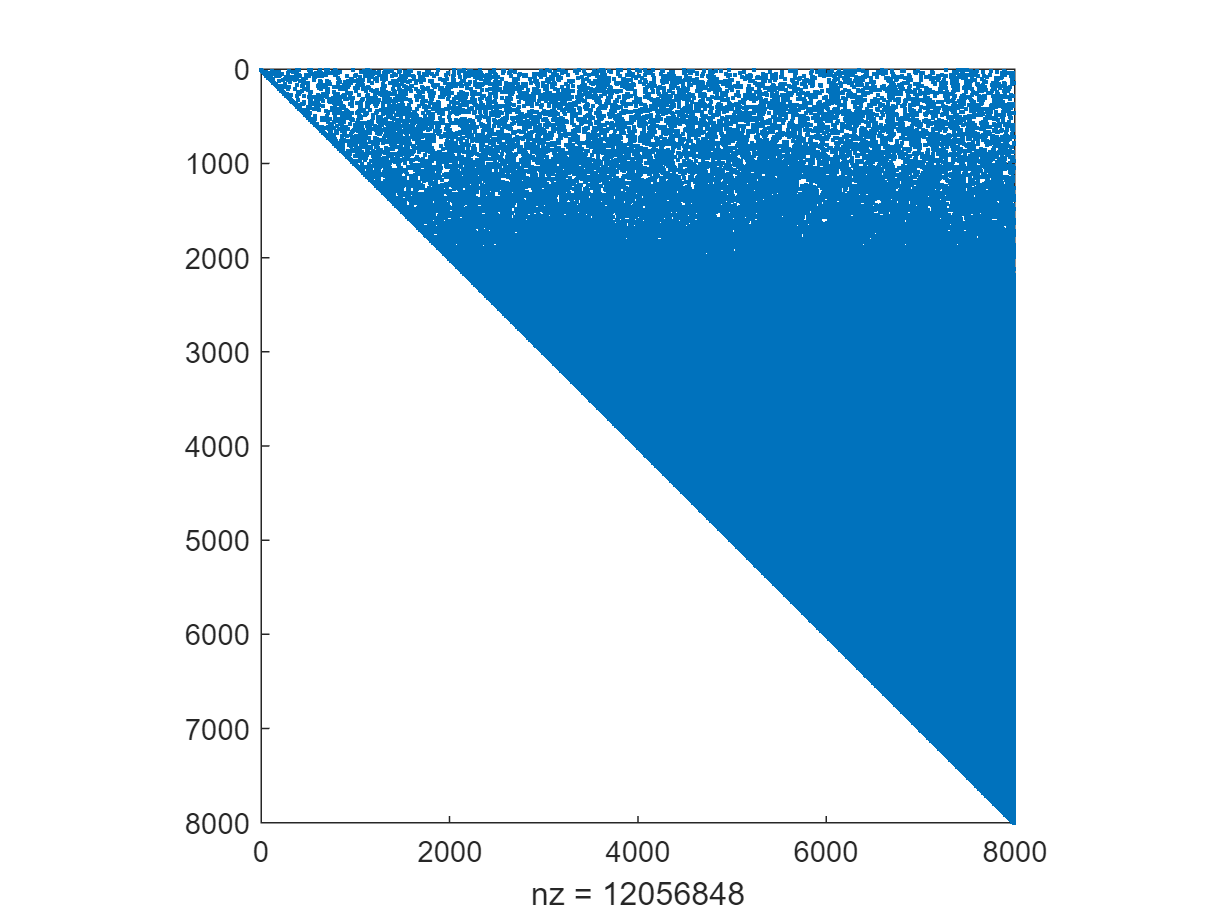

spy(rrnd)

#### c)

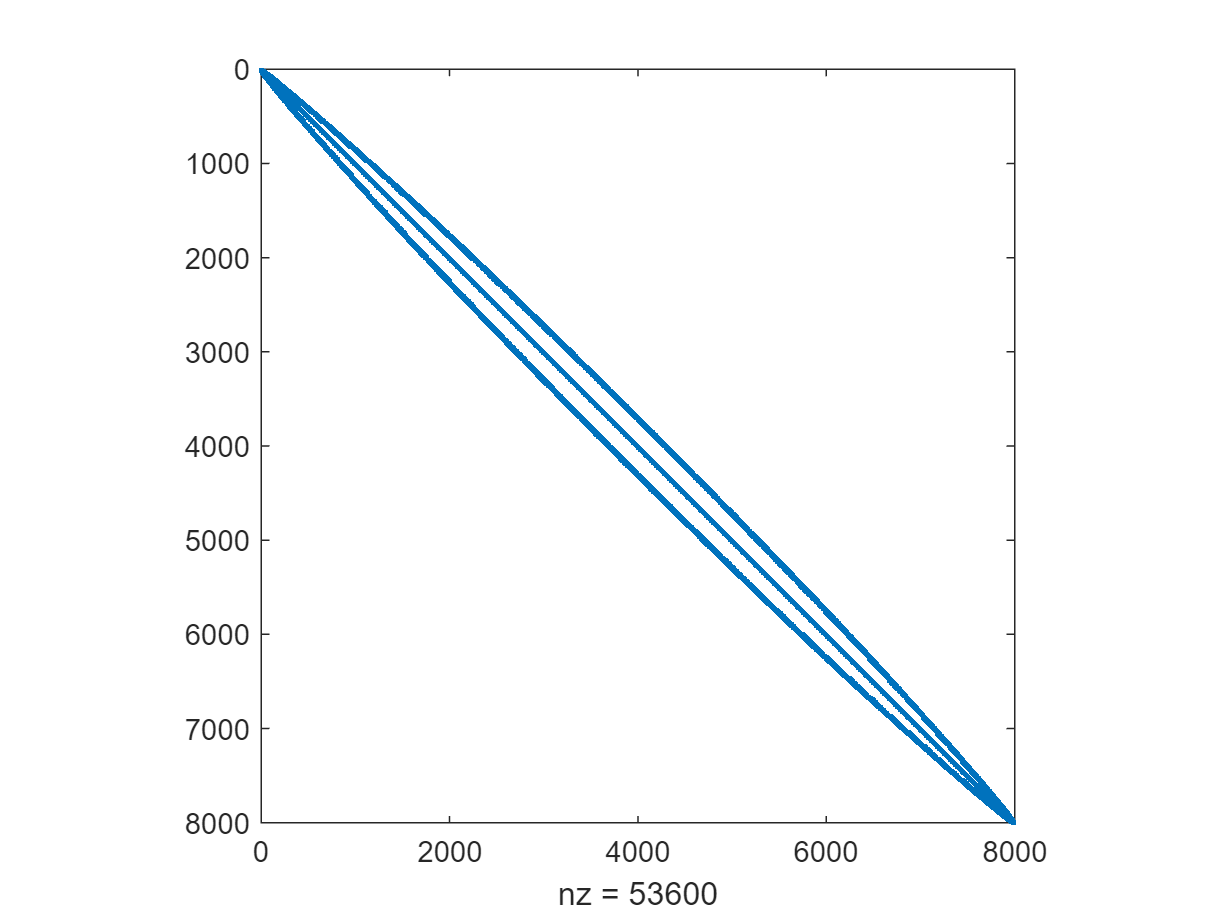

p = symrcm(A);
arcm = A(p,p);
spy(arcm)

tic, rrcm = chol(arcm); toc

历时 0.140366 秒。


nz = nnz(rrcm)

nz = 1804849

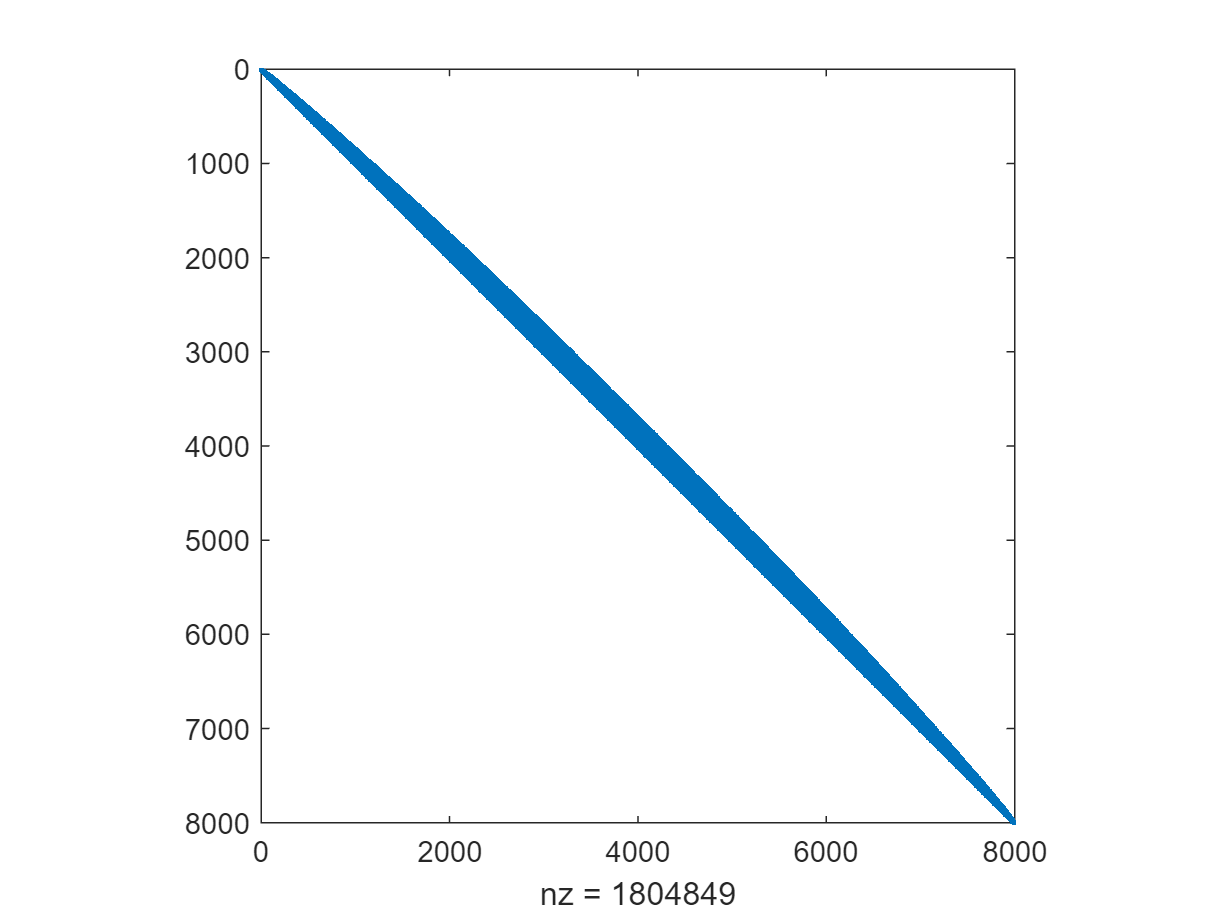

spy(rrcm)

#### d)

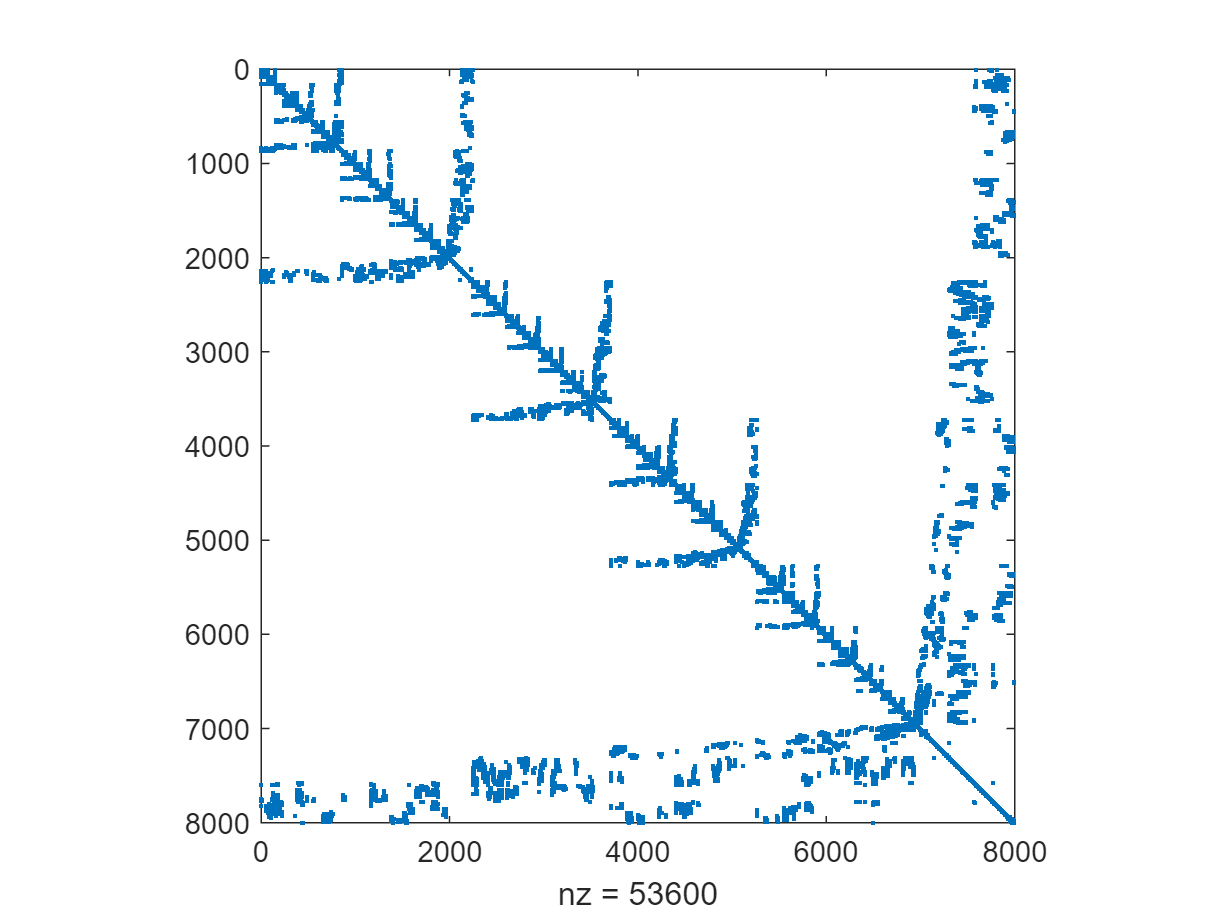

p = symamd(A);
aamd = A(p,p);
spy(aamd)

tic, ramd = chol(aamd); toc

历时 0.060410 秒。


nz = nnz(ramd)

nz = 855688

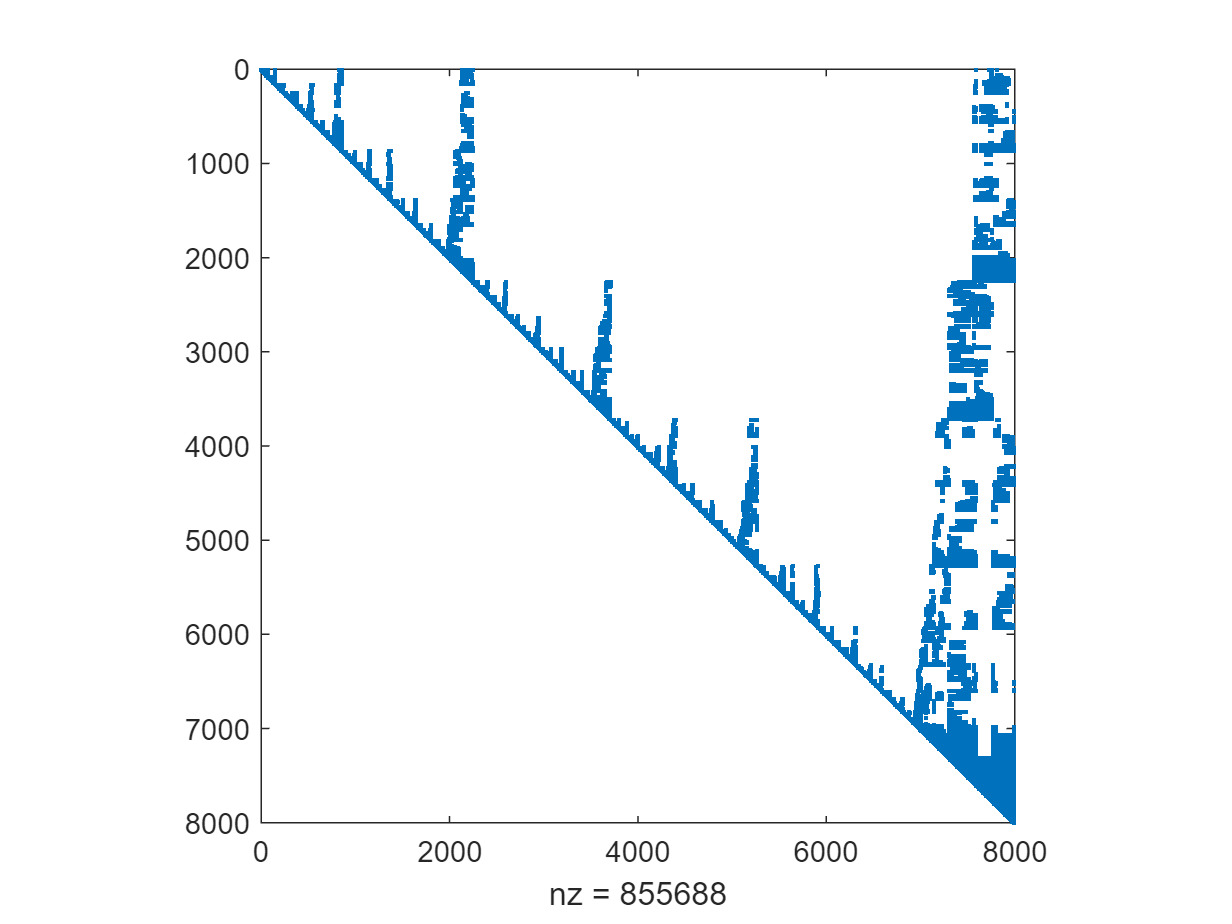

spy(ramd)

#### e)

Like the situation when m=5, the random ordering has much worse fill-in than the others. The reverse Cuthill-McKee ordering has less fill than the original banded ordering, the approximate minimum-degree ordering is the best.

### Q6

#### 1.7.10

#### a)


$$\begin{array}{l}
\det \left(2\right)=2>0\\
\det \left(\left\lbrack \begin{array}{cc}
2 & 1\\
-2 & 0
\end{array}\right\rbrack \right)=2\not= 0\\
\det \left(\left\lbrack \begin{array}{ccc}
2 & 1 & -1\\
-2 & 0 & 0\\
4 & 1 & -2
\end{array}\right\rbrack \right)=-2\not= 0\\
\det \left(\left\lbrack \begin{array}{cccc}
2 & 1 & -1 & 3\\
-2 & 0 & 0 & 0\\
4 & 1 & -2 & 6\\
-6 & -1 & 2 & -3
\end{array}\right\rbrack \right)=-6\not= 0
\end{array}$$


So, A can be transformed.

#### b)


$$\begin{array}{l}
\left\lbrack \begin{array}{ccccc}
2 & 1 & -1 & 3 & 13\\
-2 & 0 & 0 & 0 & -2\\
4 & 1 & -2 & 6 & 24\\
-6 & -1 & 2 & -3 & -14
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccccc}
2 & 1 & -1 & 3 & 13\\
0 & 1 & -1 & 3 & 11\\
0 & -1 & 0 & 0 & -2\\
0 & 2 & -1 & 6 & 25
\end{array}\right\rbrack ,m_{21} =-1,m_{31} =2,m_{41} =-3\\
\left\lbrack \begin{array}{ccccc}
2 & 1 & -1 & 3 & 13\\
0 & 1 & -1 & 3 & 11\\
0 & 0 & -1 & 3 & 9\\
0 & 0 & 1 & 0 & 3
\end{array}\right\rbrack ,m_{32} =-1,m_{42} =2\\
\left\lbrack \begin{array}{ccccc}
2 & 1 & -1 & 3 & 13\\
0 & 1 & -1 & 3 & 11\\
0 & 0 & -1 & 3 & 9\\
0 & 0 & 0 & 3 & 12
\end{array}\right\rbrack ,m_{43} =-1
\end{array}$$


So, $\left\lbrack \begin{array}{cccc}
2 & 1 & -1 & 3\\
0 & 1 & -1 & 3\\
0 & 0 & -1 & 3\\
0 & 0 & 0 & 3
\end{array}\right\rbrack x=\left\lbrack \begin{array}{c}
13\\
11\\
9\\
12
\end{array}\right\rbrack$

#### c)


$$\begin{array}{l}
b_4 =\frac{12}{3}=4\\
b_3 =\frac{9-3*4}{-1}=3\\
b_2 =\frac{11-3*4-\left(-1\right)*3}{1}=2\\
b_1 =\frac{13-3*4-\left(-1\right)*3-1*2}{2}=1
\end{array}$$


So, $x=\left\lbrack \begin{array}{c}
1\\
2\\
3\\
4
\end{array}\right\rbrack$

A = [2 1 -1 3;-2 0 0 0;4 1 -2 6;-6 -1 2 -3];
b = [13;-2;24;-14];
A\b

ans =     1.0000
    2.0000
    3.0000
    4.0000


#### 1.7.18


$$U=\left\lbrack \begin{array}{cccc}
2 & 1 & -1 & 3\\
0 & 1 & -1 & 3\\
0 & 0 & -1 & 3\\
0 & 0 & 0 & 3
\end{array}\right\rbrack ,L=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
-1 & 1 & 0 & 0\\
2 & -1 & 1 & 0\\
-3 & 2 & -1 & 1
\end{array}\right\rbrack ,\hat{b} =\left\lbrack \begin{array}{c}
12\\
-8\\
21\\
-26
\end{array}\right\rbrack$$


Forward


$$\begin{array}{l}
\textrm{Ly}=\hat{b} \\
y_1 =12\\
y_2 =-8+12=4\\
y_3 =21-2*12+4=1\\
y_4 =-26+3*12-2*4+1=3\\
y=\left\lbrack \begin{array}{c}
12\\
4\\
1\\
3
\end{array}\right\rbrack 
\end{array}$$


Backward


$$\begin{array}{l}
\textrm{Ux}=y\\
x_4 =\frac{3}{3}=1\\
x_3 =\frac{1-3*1}{-1}=2\\
x_2 =4+2-3*1=3\\
x_1 =\frac{12-3+2-3*1}{2}=4\\
x=\left\lbrack \begin{array}{c}
4\\
3\\
2\\
1
\end{array}\right\rbrack 
\end{array}$$


A = [2 1 -1 3;-2 0 0 0;4 1 -2 6;-6 -1 2 -3];
b = [12;-8;21;-26];
A\b

ans =     4.0000
    3.0000
    2.0000
    1.0000


### Q7

#### a)


$$M=\left\lbrack \begin{array}{ccccccc}
1 &  &  &  &  &  & \\
 & \ddots  &  &  &  &  & \\
 &  & 1 &  &  &  & \\
 &  &  & \ddots  &  &  & \\
 &  & m &  & 1 &  & \\
 &  &  &  &  & \ddots  & \\
 &  &  &  &  &  & 1
\end{array}\right\rbrack$$


consider MA.

Suppose that m is in ith row, jth column.

Using the definition of matrix multiplication,

for each row other than ith row, $\hat{a_{k\not= i,l} } =a_{k\not= i,l}$

for the ith row, $\hat{a_{i,l} =} m*a_{j,l} +a_{i,l}$

Therefore, $\textrm{MA}=\left\lbrack \begin{array}{cccccc}
a_{11}  & a_{12}  &  & \cdots  &  & a_{1n} \\
a_{21}  & a_{22}  &  & \cdots  &  & a_{2n} \\
\cdots  & \cdots  &  & \cdots  &  & \cdots \\
m*a_{\textrm{j1}} +a_{\textrm{i1}}  & m*a_{\textrm{j2}} +a_{\textrm{i2}}  &  & \cdots  &  & m*a_{\textrm{jn}} +a_{\textrm{jn}} \\
\cdots  & \cdots  &  & \cdots  &  & \cdots \\
a_{\textrm{n1}}  & a_{\textrm{n2}}  &  & \cdots  &  & a_{\textrm{nn}} 
\end{array}\right\rbrack$

This is exactly $\hat{A}$. Therefore $\hat{A} =\textrm{MA}$.

#### b)


$$\det \left(M\right)=\det \left(\left\lbrack \begin{array}{ccccccc}
1 &  &  &  &  &  & \\
 & \ddots  &  &  &  &  & \\
 &  & 1 &  &  &  & \\
 &  &  & \ddots  &  &  & \\
 &  & m &  & 1 &  & \\
 &  &  &  &  & \ddots  & \\
 &  &  &  &  &  & 1
\end{array}\right\rbrack \right)=1*1*\cdots *1*\det \left(\left\lbrack \begin{array}{ccccc}
1 &  &  &  & \\
 & \ddots  &  &  & \\
m &  & 1 &  & \\
 &  &  & \ddots  & \\
 &  &  &  & 1
\end{array}\right\rbrack \right)=1*\det \left(I\right)\pm m*0=1$$


Since each first j-1 column has only one nonzero 1, others are zero, we can generate *1 until jth row.

The sub-determinant $\det \left(\left\lbrack \begin{array}{ccccc}
1 &  &  &  & \\
 & \ddots  &  &  & \\
m &  & 1 &  & \\
 &  &  & \ddots  & \\
 &  &  &  & 1
\end{array}\right\rbrack \right)$ shows that the sub-determinant of 1 is still 1, the sub-determinant of m is singlar matrix.

Therefore, $\det \left(M\right)=1$.

Since $\det \left(\textrm{AB}\right)=\det \left(A\right)\cdot \det \left(B\right)$

So $\det \left(\hat{A} \right)=\det \left(\textrm{MA}\right)=\det \left(M\right)\cdot \det \left(A\right)=\det \left(A\right)$.

#### c)


$$M^{-1} =\left\lbrack \begin{array}{ccccccc}
1 &  &  &  &  &  & \\
 & \ddots  &  &  &  &  & \\
 &  & 1 &  &  &  & \\
 &  &  & \ddots  &  &  & \\
 &  & -m &  & 1 &  & \\
 &  &  &  &  & \ddots  & \\
 &  &  &  &  &  & 1
\end{array}\right\rbrack$$


$M^{-1}$ means minusing m times the jth row to the ith row.

### Q8

#### 1.8.12

Please refer to Gauss.m

#### 1.8.15

Please refer to SolveG.m

A = [2 10 8 8 6;1 4 -2 4 -1;0 2 3 2 1;3 8 3 10 9;1 4 1 2 1];
b = [52;14;12;51;15];
c = [50;4;12;48;12];
[flag, intch, a] = Gauss(A)

flag = 0

intch =      4     4     4     5     5


a =     3.0000    8.0000    3.0000   10.0000    9.0000
    0.6667    4.6667    6.0000    1.3333         0
    0.3333    0.2857   -4.7143    0.2857   -4.0000
    0.3333    0.2857    0.3636   -1.8182   -0.5455
         0    0.4286   -0.0909   -0.8000    0.2000


[flag, x] = SolveG(a, b, intch)

flag = 0

x =     1.0000
    2.0000
    1.0000
    2.0000
    1.0000


[flag, x] = SolveG(a, c, intch)

flag = 0

x =     2.0000
    1.0000
    2.0000
    1.0000
    2.0000


### Q9

Without pivoting

for k=1:n-1

for j=k+1:n

L(j,k) = U(j,k) / U(k,k)

U(j,k:n) = U(j,k:n) - L(j,k)U(k,k:n)

GE without pivoting, for each diagnal element $a_{\textrm{ss}}$, we have 2 operations * and -, and operate for s^2 times.

$\textrm{flops}=2*\left(n^2 +{\left(n-1\right)}^2 +{\left(n-2\right)}^2 +\cdots +1\right)=\frac{2\left(n+1\right)n\left(2n+1\right)}{6}\approx \frac{{2n}^3 }{3}$.

Solving Ly = b and Ux = y requires about $2n^2$ flops.

Partial pivoting $\textrm{flops}=\left(n-1\right)+\left(n-2\right)+\cdots +1=\frac{n\left(n-1\right)}{2}\approx \frac{n^2 }{2}$.

Complete pivoting requires$\;\textrm{flops}=n^2 +{\left(n-1\right)}^2 +{\left(n-2\right)}^2 +\cdots +1=\frac{\left(n+1\right)n\left(2n+1\right)}{6}\approx \frac{n^3 }{3}$.

### Q10

#### 2.2.28

for n = [3 6 9]
    A = hilb(n);
    condest(A)
    cond(A, 1)
    fprintf('------------------------------\n')
end

ans = 748.0000

ans = 748.0000

------------------------------


ans = 2.9070e+07

ans = 2.9070e+07

------------------------------


ans = 1.0997e+12

ans = 1.0996e+12

------------------------------


#### 2.6.6

for n = [4 8 12]
    z = ones(n, 1);
    H = hilb(n);
    b = H * z;
    xhat = H \ b;
    k = cond(H, 2)
    deltax = norm(xhat - z, 2)
    rhat = norm(b - H * xhat, 2)
    fprintf('------------------------------\n')
end

k = 1.5514e+04

deltax = 7.7236e-13

rhat = 1.1102e-16

------------------------------


k = 1.5258e+10

deltax = 6.0931e-07

rhat = 4.5776e-16

------------------------------


k = 1.6212e+16

deltax = 0.5757

rhat = 7.0217e-16

------------------------------
